## Homework 3, problem 1a

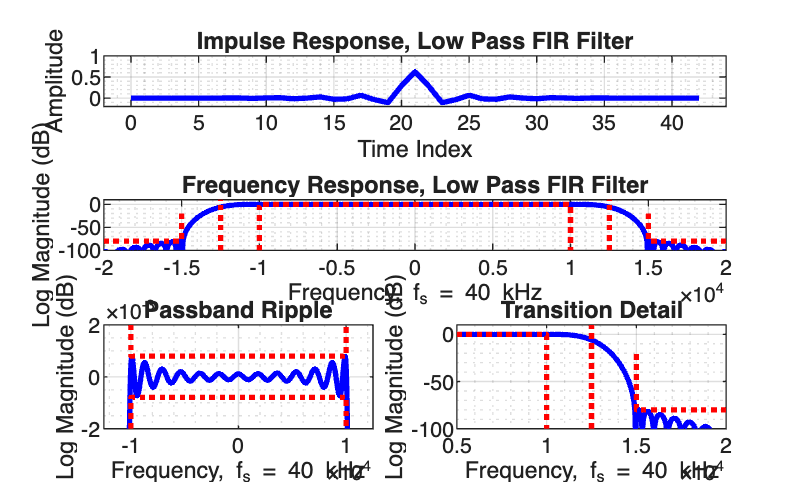

%% Homework 3, problem 1a

clc; clear; close all;

% Following code is leveraged from Prof. harris' problem statement 3
fs = 40000; % Sample rate
f1 = 10000; % Passband frequency
f2 = 15000; % Stopband frequency
A_dB = 80; % Stopband attenuation

Beta = A_dB / 10;

% Calculate the filter length using harris approximation
M = floor((fs / (f2 - f1)) * A_dB / 15);

% If M is even, make it odd
if (M - 2 * ceil(M / 2) == 0)
  M = M + 1;
end

MM = (M - 1) / 2;
phi = 2 * pi * (-MM : MM) * (f1 + f2) / (2 * fs);

% Compute unscaled sinc filter h
h = sin(phi) ./ phi;

% Correct failed 0/0 computation
h(MM + 1) = 1;

h0 = h .* kaiser(2 * MM + 1, Beta)';
h1 = h0 * (f2 + f1) / fs;

figure(1)
subplot(3, 1, 1)
plot(0 : 2 * MM, h1, "b", "LineWidth", 2);
grid on;
grid minor;
axis([-2, 2 * MM + 2, -0.2 1]);
title("Impulse Response, Low Pass FIR Filter");
xlabel("Time Index");
ylabel("Amplitude");

f_h1 = fftshift(20 * log10(abs(fft(h1, 1024))));
subplot(3, 1, 2);
plot((-0.5 : 1/1024 : 0.5 - 1/1024) * fs, f_h1, "b", "LineWidth", 2);
hold on;
% Show the stopback frequency and gain
plot([-fs/2 -f2 -f2], [-80 -80 -20], ":r", "LineWidth", 2);
plot([fs/2 f2 f2], [-80 -80 -20], ":r", "LineWidth", 2);
% Show the passband frequency
plot([-f1 -f1 f1 f1], [-100 0 0 -100], ":r", "LineWidth", 2);
% Show the 6dB frequency (midway between passband and stopband)
f0 = (f1 + f2) / 2;
plot([-f0 -f0], [-100 10], ":r", "LineWidth", 2);
plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on;
grid minor;
axis([-fs/2 fs/2 -100 10]);
title("Frequency Response, Low Pass FIR Filter");
xlabel(sprintf("Frequency, f_s = %d kHz", fs/1000));
ylabel("Log Magnitude (dB)");

subplot(3, 2, 5);
plot((-0.5 : 1/1024 : 0.5 - 1/1024) * fs, f_h1, "b", "LineWidth", 2);
hold on;
plot(...
  [-f1 -f1 f1 f1], [-0.002 -max(f_h1) -max(f_h1) -0.002], ":r", "LineWidth", 2);
plot([-f1 -f1 f1 f1], [0.002 max(f_h1) max(f_h1) 0.002], ":r", "LineWidth", 2);
hold off;
grid on;
grid minor;
axis([-f0 f0 -0.002 0.002]);
title("Passband Ripple");
xlabel(sprintf("Frequency, f_s = %d kHz", fs/1000));
ylabel("Log Magnitude (dB)");

subplot(3, 2, 6);
plot((-0.5 : 1/1024 : 0.5-1/1024) * fs, f_h1, "b", "LineWidth", 2);
hold on;
plot([f1/2 f1 f1], [0 0 -100], ":r", "LineWidth", 2);
plot([f2+f1/2 f2 f2], [-80 -80 -20], ":r", "LineWidth", 2);
plot([+f0 +f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on;
grid minor;
axis([f1/2 f2+f1/2 -100 10]);
title("Transition Detail");
xlabel(sprintf("Frequency, f_s = %d kHz", fs/1000));
ylabel("Log Magnitude (dB)");

Computing peak linear deviation:

max(f_h1) = 1.0018

Deviation from desired passband gain of 1 = 0.0018 (0.18%)

For window designs, deviation from desired stopband gain of 0 is equal to the desired passband gain of 1.

## Homework 3, problem 1b

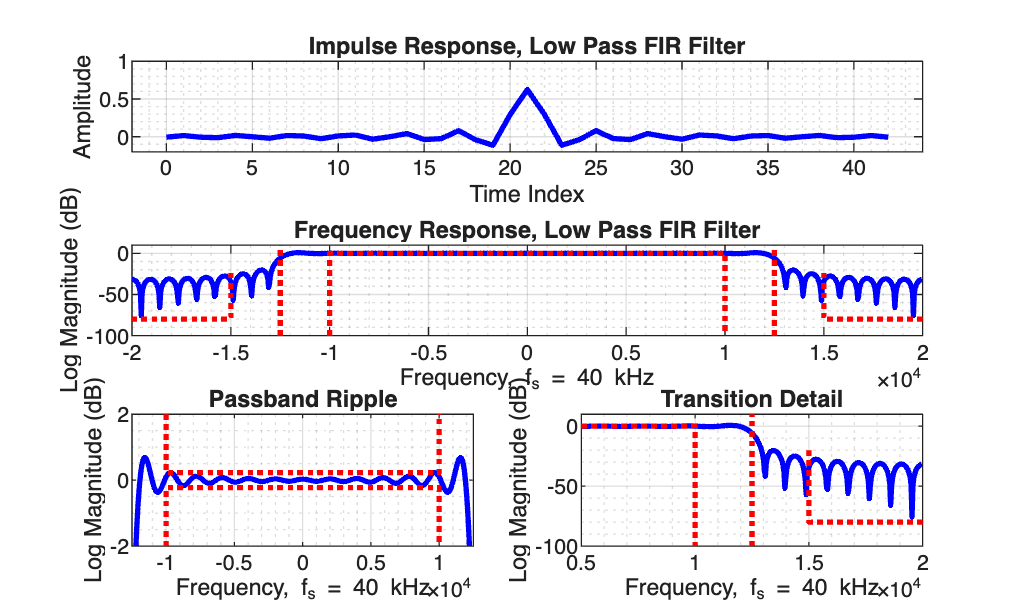

%% Homework 3, problem 1b

clc; clear;
fs = 40000; % Sample rate
f1 = 10000; % Passband frequency
f2 = 15000; % Stopband frequency
A_dB = 80; % Stopband attenuation

% Calculate the filter length using harris approximation
M = floor((fs / (f2 - f1)) * A_dB / 15);

% If M is even, make it odd
if (M - 2 * ceil(M / 2) == 0)
  M = M + 1;
end

MM = (M - 1) / 2;
phi = 2 * pi * (-MM : MM) * (f1 + f2) / (2 * fs);

% Compute unscaled sinc filter h
h = sin(phi) ./ phi;

% Correct failed 0/0 computation
h(MM + 1) = 1;
h1 = h .* (f2 + f1) / fs; % Normalization only

figure(2)
subplot(3, 1, 1)
plot(0 : 2 * MM, h1, "b", "LineWidth", 2);
grid on;
grid minor;
axis([-2, 2 * MM + 2, -0.2 1]);
title("Impulse Response, Low Pass FIR Filter");
xlabel("Time Index");
ylabel("Amplitude");

f_h1 = fftshift(20 * log10(abs(fft(h1, 1024))));
subplot(3, 1, 2);
plot((-0.5 : 1/1024 : 0.5 - 1/1024) * fs, f_h1, "b", "LineWidth", 2);
hold on;
% Show the stopback frequency and gain
plot([-fs/2 -f2 -f2], [-80 -80 -20], ":r", "LineWidth", 2);
plot([fs/2 f2 f2], [-80 -80 -20], ":r", "LineWidth", 2);
% Show the passband frequency
plot([-f1 -f1 f1 f1], [-100 0 0 -100], ":r", "LineWidth", 2);
% Show the 6dB frequency (midway between passband and stopband)
f0 = (f1 + f2) / 2;
plot([-f0 -f0], [-100 10], ":r", "LineWidth", 2);
plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on;
grid minor;
axis([-fs/2 fs/2 -100 10]);
title("Frequency Response, Low Pass FIR Filter");
xlabel(sprintf("Frequency, f_s = %d kHz", fs/1000));
ylabel("Log Magnitude (dB)");

subplot(3, 2, 5);

plot((-0.5 : 1/1024 : 0.5 - 1/1024) * fs, f_h1, "b", "LineWidth", 2);
hold on;
% Passband frequency is fs/4; hence checking ripple in 255:755 range
max_dev = max(f_h1(255:755));
plot(...
  [-f1 -f1 f1 f1], [-2 -max_dev -max_dev -2], ":r", "LineWidth", 2);
plot([-f1 -f1 f1 f1], [2 max_dev max_dev 2], ":r", "LineWidth", 2);
hold off;
grid on;
grid minor;
axis([-f0 f0 -2 2]);
title("Passband Ripple");
xlabel(sprintf("Frequency, f_s = %d kHz", fs/1000));
ylabel("Log Magnitude (dB)");

subplot(3, 2, 6);

plot((-0.5 : 1/1024 : 0.5-1/1024) * fs, f_h1, "b", "LineWidth", 2);
hold on;
plot([f1/2 f1 f1], [0 0 -100], ":r", "LineWidth", 2);
plot([f2+f1/2 f2 f2], [-80 -80 -20], ":r", "LineWidth", 2);
plot([+f0 +f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on;
grid minor;
axis([f1/2 f2+f1/2 -100 10]);
title("Transition Detail");
xlabel(sprintf("Frequency, f_s = %d kHz", fs/1000));
ylabel("Log Magnitude (dB)");

Computing peak linear deviation:

max(f_h1) = 1.0266

Deviation from desired passband gain of 1 = 0.0266 (2.66%)

By inspection, deviation from desired stopband gain of 0 (stopband ripple) is significantly more than the window design of 1a).

The passband ripple is about 15 times more in magnitude than 1a).

The transition bandwidth has significantly less attenuation compared to 1a).

## Homework 3, problem 1c

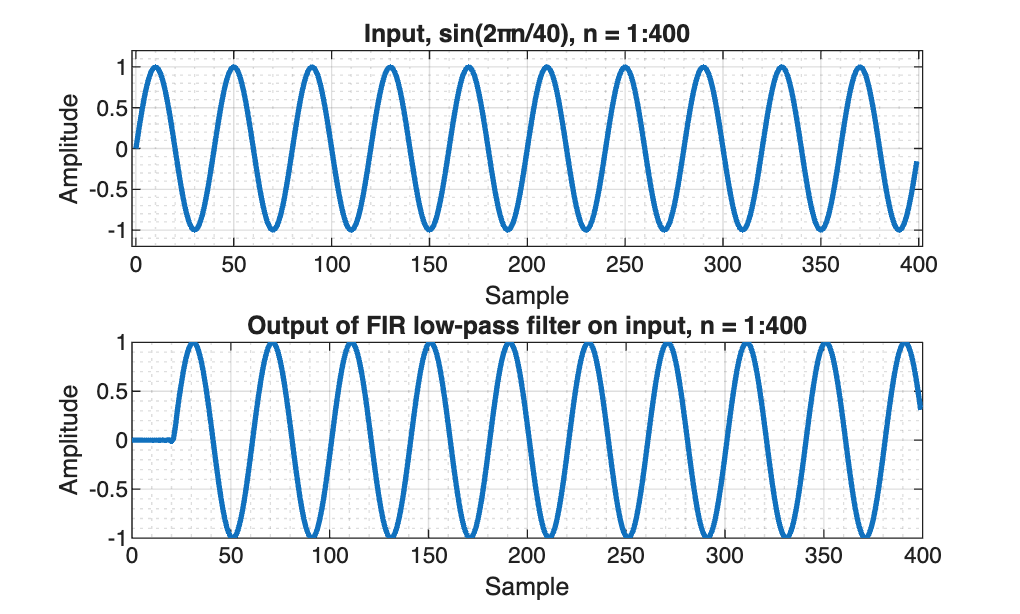

%% Homework 3, problem 1c

% Helper function to plot an input signal and output of a filter (given its
% transfer function).
% Parameters:
%   n - Sample number
%   n_output - Number of input/output samples to plot
%   h - Filter transfer function (time domain)
%   x - Input
%   title - Title for input
function plot_filter_output(n, n_output, h, x, in_title)
  n = n(1:n_output);
  figure;
  subplot(2, 1, 1);
  plot(n, x(1:n_output), "LineWidth", 2);
  xlabel("Sample"); ylabel("Amplitude");
  title(sprintf("Input, %s, n = 1:%d", in_title, n_output));
  grid on; grid minor;
  axis on;
  axis([-2, n_output + 2, min(x) - 0.2, max(x) + 0.2]);

  subplot(2, 1, 2);
  % Time domain response will be be convolution of h1 with the input signals
  y = conv(h, x);
  plot(n, y(1:n_output), "LineWidth", 2);
  xlabel("Sample"); ylabel("Amplitude");
  title(...
    sprintf(...
    "Output of FIR low-pass filter on input, n = 1:%d", n_output));
  grid on; grid minor;
  axis on;
  axis(-2, n_output + 2, min(y) - 0.2, max(y) + 0.2);
end

fs = 40000; % Sample rate
n_max = 1000; % Number of samples

% Center frequencies (1 KHz & 19 KHz)
f_a = 1000;
f_b = 19000;

% Converting to digital frequencies (radians per sample)
w_a = 2 * pi * f_a / fs;
w_b = 2 * pi * f_b / fs;

n = [0 : n_max - 1];
x_a = sin(w_a * n);
x_b = sin(w_b * n);
x_c = x_a + x_b;

% Reproducing filter from 1a
f1 = 10000; % Passband frequency
f2 = 15000; % Stopband frequency
A_dB = 80; % Stopband attenuation

Beta = A_dB / 10;

% Calculate the filter length using harris approximation
M = floor((fs / (f2 - f1)) * A_dB / 15);

% If M is even, make it odd
if (M - 2 * ceil(M / 2) == 0)
  M = M + 1;
end

MM = (M - 1) / 2;
phi = 2 * pi * (-MM : MM) * (f1 + f2) / (2 * fs);

% Compute unscaled sinc filter h
h = sin(phi) ./ phi;

% Correct failed 0/0 computation
h(MM + 1) = 1;

h0 = h .* kaiser(2 * MM + 1, Beta)';
h1 = h0 * (f2 + f1) / fs;

plot_filter_output(n, 400, h1, x_a, "sin(2πn/40)");

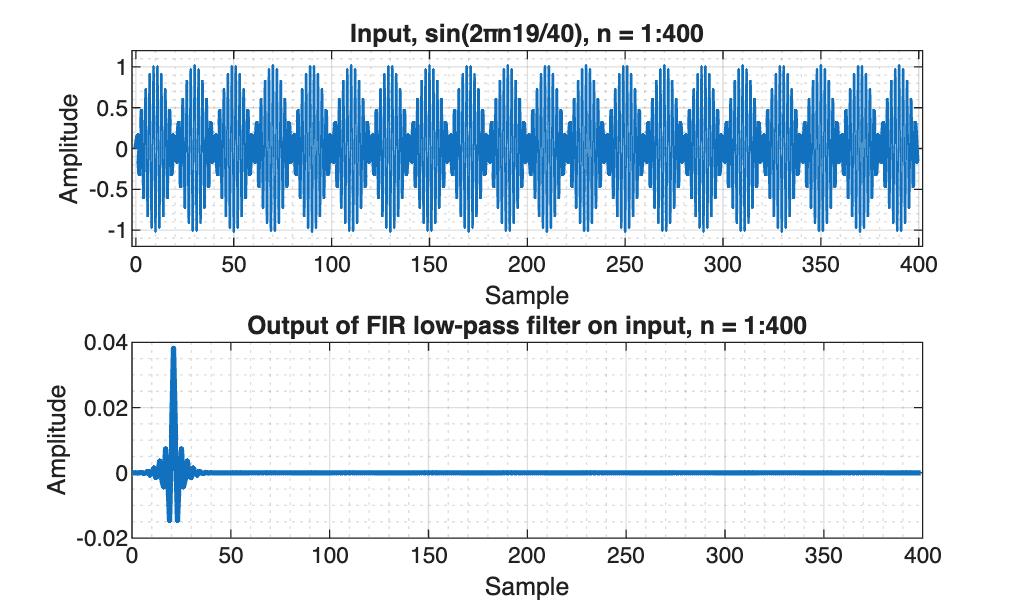

plot_filter_output(n, 400, h1, x_b, "sin(2πn19/40)");

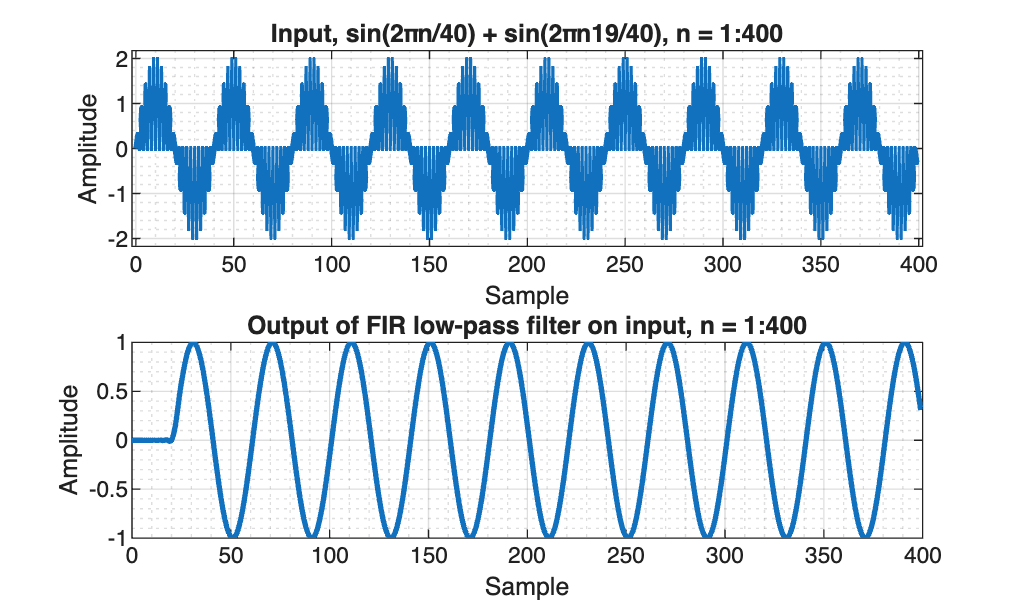

plot_filter_output(n, 400, h1, x_c, "sin(2πn/40) + sin(2πn19/40)");